# 1. Тестирование извлечения гармоник из спектра

## Красницкий Никита

Задача: убедится в правильности работы функции 

HarmonicsExtraction(x, fs, MinFreqStep,MinAmplitude)

на основе той же функции но с выводами промежуточного и конечного графика

HarmonicsExtractionPlot(x, fs, MinFreqStep,MinAmplitude)

# 1.1 Cумма гармонических колебаний

Создаю сумму гармонических колебаний разных частот с известными разными амплитудами. Как видно из спектра - высоты пиков соответствуют половине амплитуды на соответствующей частоте.

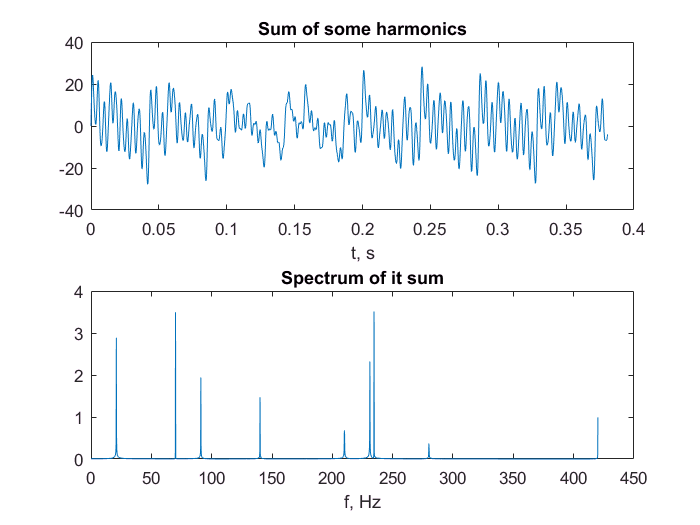

clear all
close all
clc
load('1.Load Data.mat');

F0 = 70;
A  = [6     7  4    3   2  5    7     1  2];
F  = [0.3   1  1.3  2   3  3.3  3.35  4  6] * F0;
F  = F + rand(1,length(F))/10;
s = A*sin(2*pi*F'*t);
FewPeriods = floor(8 * N/(F(1)*Ts));
S = abs(fftshift(fft(s))) /N;
f1 = floor(N/2+1);
f2 = floor(f1 + N*F(end)/fs + 1);

figure
subplot(2,1,1);
plot(t(1:FewPeriods), s(1:FewPeriods));
title('Sum of some harmonics');
xlabel('t, s');

subplot(2,1,2);
plot(f(f1:f2), S(f1:f2));
title('Spectrum of it sum');
xlabel('f, Hz');

Результат использования функции HarmonicsExtractionPlot

?????????? ??????? ???????? - 2  4  0  2  1  0  0  0


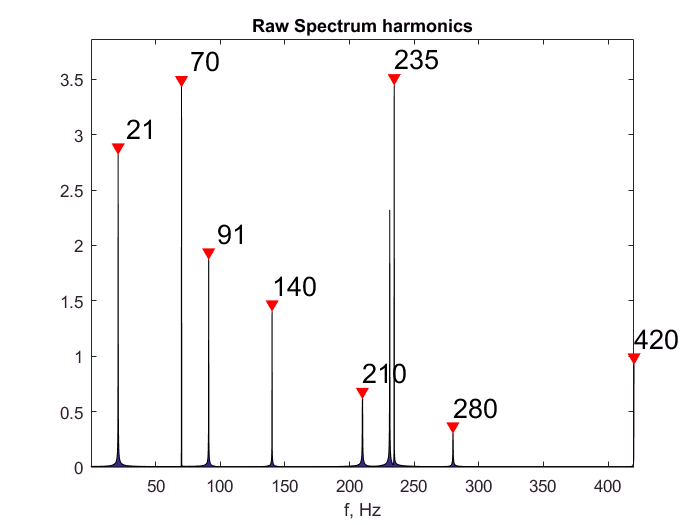

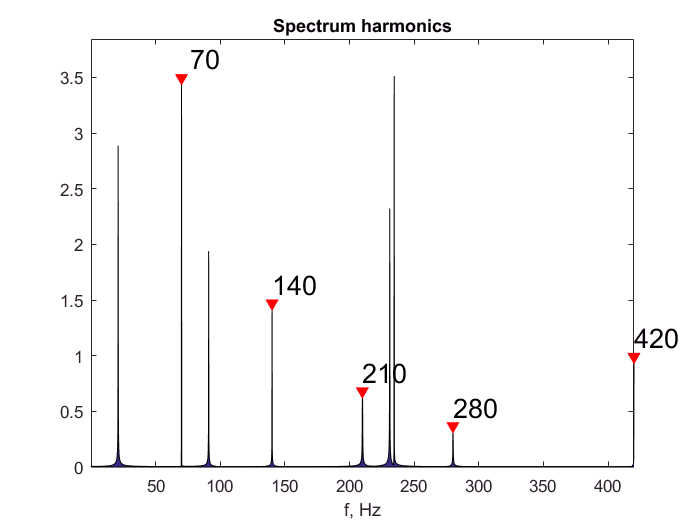

s = s';
[Fharm, psk] = HarmonicsExtractionPlot(s, fs, 5, 0.1);

## Добавление шума

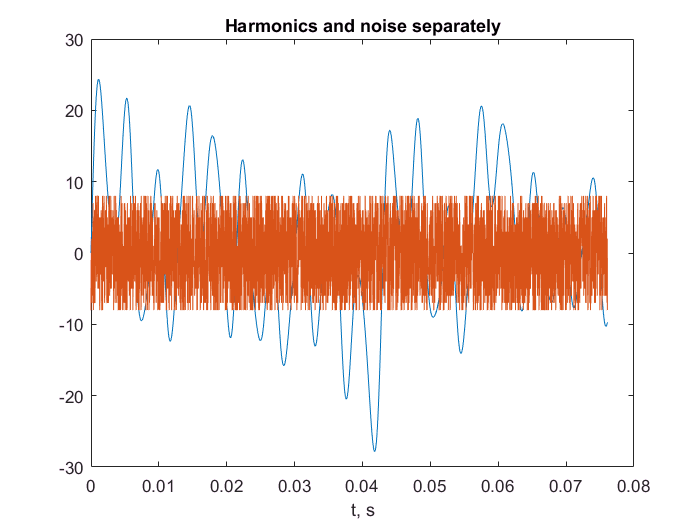

s     = A*sin(2*pi*F'*t);
noise = randi([-8, 8], 1, N);
sn    = s+noise;
FewPeriods = round(FewPeriods/5);

figure
plot(t(1:FewPeriods), s(1:FewPeriods));
hold on
plot(t(1:FewPeriods), noise(1:FewPeriods));
title('Harmonics and noise separately');
xlabel('t, s');

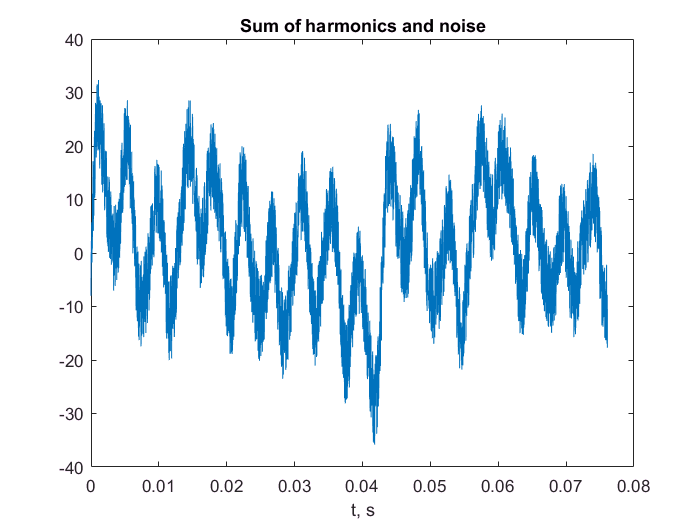



figure
plot(t(1:FewPeriods), sn(1:FewPeriods));
title('Sum of harmonics and noise');
xlabel('t, s');

Для аудиального оценивания влияния шума можно прослушать колебание до и после добавления шума (убавьте динамики, звуки не самые приятные)

%sound(s,  fs);
%sound(sn, fs);

Спектр зашумленного звука

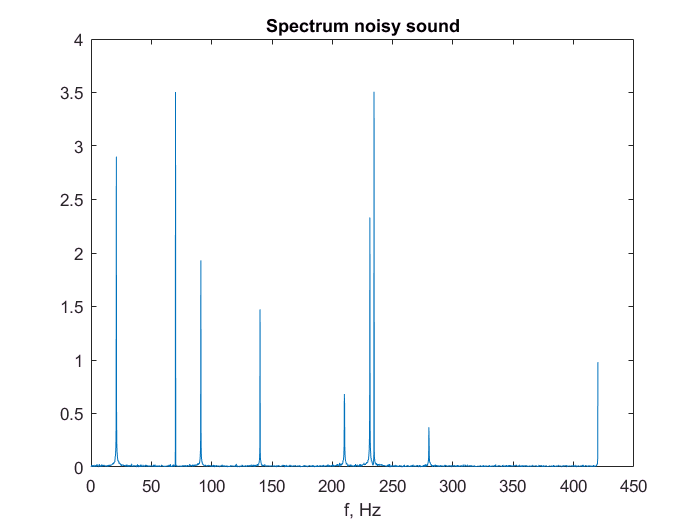

Sn = abs(fftshift(fft(sn)))/N;

figure
plot(f(f1:f2), Sn(f1:f2));
title('Spectrum noisy sound');
xlabel('f, Hz');

Результат использования алгоритма

sn = sn';
disp('Min Freq step = default, Min height = default');

Min Freq step = default, Min height = default


?????????? ??????? ???????? - 2  4  0  2  1  0  0  0


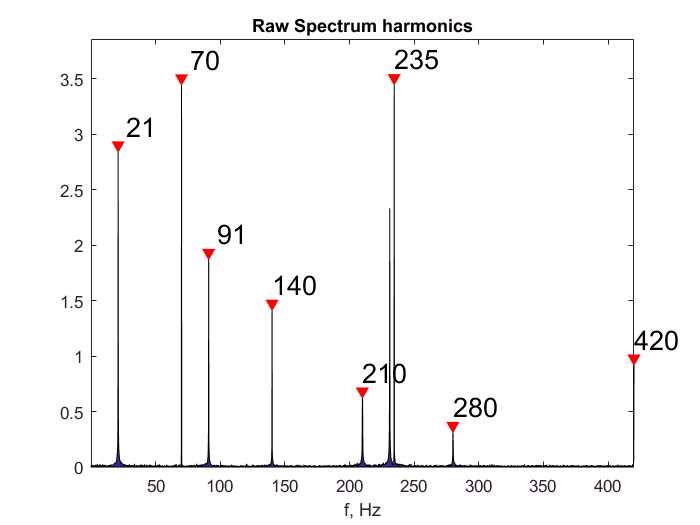

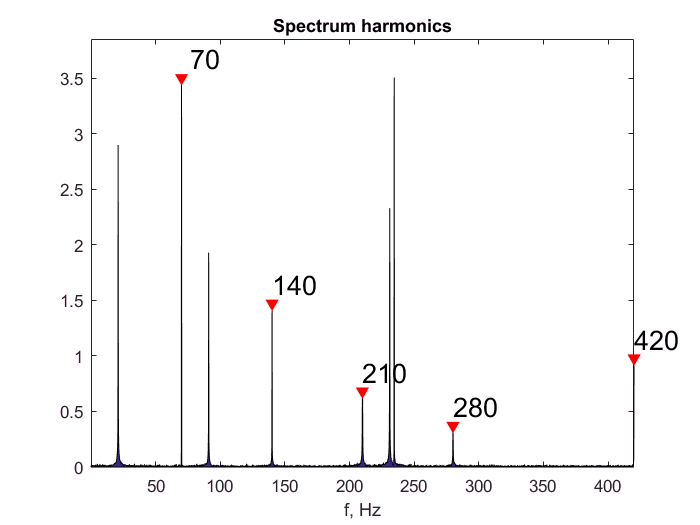

[Fharm, pskNoise] = HarmonicsExtractionPlot(sn, fs, 0, 0);


disp('Max difference in height of harmonic by noise - ');

Max difference in height of harmonic by noise - 


disp(num2str(max(abs(psk - pskNoise))));

0.01101


Результат использования алгоритма при неоптимальных параметраг шага частот и минимальной высоты

disp('Min Freq step = 10Hz, Min height = 0.1');

Min Freq step = 10Hz, Min height = 0.1


?????????? ??????? ???????? - 2  4  0  2  1  0  0  0


[Fharm, psk] = HarmonicsExtractionPlot(sn, fs, 10, 0.1);


disp('Min Freq step = 5Hz, Min height = 0.02');

Min Freq step = 5Hz, Min height = 0.02


?????????? ??????? ???????? - 134   97   90  102   97  113  106  101   93   97   97  112   99   93   90  103   92   97   87   87   99   91   82   96   94   87  103   95   99   88   97   82   96   99   83   99   89   83   81   98   86   86   95   93  100   88   96   81   91   96   96   91  100   95  100   98   97   89   98  103   92   90   87   96   96   94   97   95   82   96   96   90   91   88   90   92  108   78   87   93   88   94   80   93   85   84   89   84   89   88   87   84   82   96   91   93   93   86   95   96   89   91   91   92   90   91   88   86   87   91   74   85   73   91   88   85   99   83   88   84   87   87  104   90   88   90   84   83   78   74   93   88   93   93   85   80   81   80   81   84   92   90   92   87   83   98   99   94   90   83   80   88   80   80   85   77   82   84   85   86   81   76   73   76   81   94   91   96   93   92   89   90   85   86   88   87   81   88   87   84   78   66   66   62   72   75   62   62   63   80   83   85   85   84  

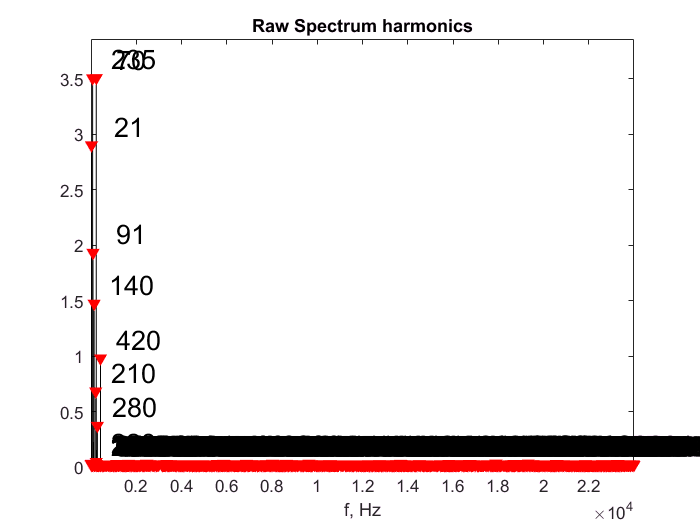

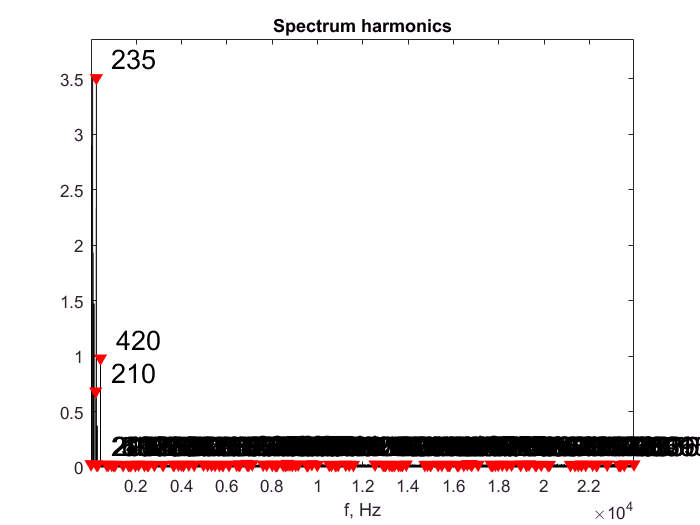

[Fharm, psk] = HarmonicsExtractionPlot(sn, fs, 5, 0.02);

Выводы: 

- Из примеров выше видно, что алгоритм выбирает из спектра только локальные максимумы спектра на кратных частотах. 

- Небольшой шум никак не влияет на позиционирование гармоник. В примере максимальное изменение высоты гармоники от действия шума меньше одной сотой (>1%). Значит наличие шума не будет отражаться на исследовании высоты гармоники во времени.

- При неправильных параметрах шага частот и минимальной высоты алгоритм может выдать неблагоприятный результат, как показано на последнем графике. От того, что слишком много локальных максимумов шума было захвачено, нашлись такие, которые оказались кратными для выбранного основного тона. Из-за чего "Отфильтрованый набор" гармоник не избавился от шумовых составляющих. По этому не рекомендуется задавать слишком низкий порог амплитуды.

- Рекомендуется не задавать предварительно порог амплитуды и вписать в этот параметр 0 (ноль), как показано в первом случае с добавлением шума. В таком случае алгоритм найдет максимальную неотфильтрованую гармонику и задаст амплитудный порог как 1% от максимальной амплитуды.

# 1.2 Применение к воспроизведению известной ноты на музыкальном инструменте